fid = fopen("type1000.tmp");
bh = readBlueFileHeader(fid);
fclose(fid);

direName = "C:\Users\bergm\GIT25\ZDATA00\epsilon";
cd( direName );
fileList = dir('SDR*IQ.wav');
disp(fileList);

       name: 'SDRSharp_20251222_205337Z_10021000Hz_IQ.wav'
     folder: 'C:\Users\bergm\GIT25\ZDATA00\epsilon'
       date: '22-Dec-2025 15:53:59'
      bytes: 4995116
      isdir: 0
    datenum: 7.3997e+05



****************


pathName = "C:\Users\bergm\GIT25\ZDATA00\epsilon\SDRSharp_20251222_205337Z_10021000Hz_IQ.wav"

fileNameSplit = 1×2 cell array
    {'SDRSharp_20251222_205337Z_10021000Hz_IQ'}    {'wav'}


whogi = 1×5 cell array
    {'SDRSharp'}    {'20251222'}    {'205337Z'}    {'10021000Hz'}    {'IQ'}


yyyymmdd = '20251222'

yyyy =         2025


mm =     12


dd =     22


hhmnss = '205337Z'

hh =     20


mn =     53


ss =     37


ts =    2.3976e+09


cfStr = '10021000Hz'

cf =     10021000


meta = struct with fields:
             Filename: 'C:\Users\bergm\GIT25\ZDATA00\epsilon\SDRSharp_20251222_205337Z_10021000Hz_IQ.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 57000
         TotalSamples: 1248768
             Duration: 21.908
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


char
char
char
int32
int32
int32
int32
int32
int32
int32
double
double
int32
char


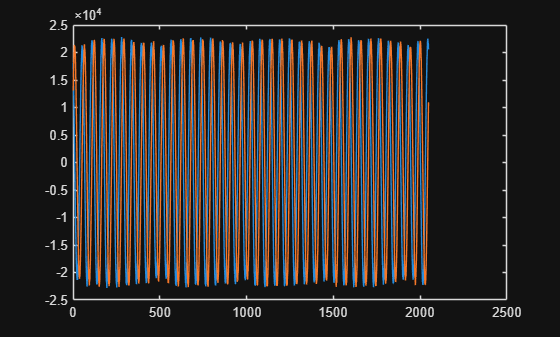

****************



for ii = 1:length(fileList)
  disp("****************")
  fileName = fileList(ii).name;
  pathName = strcat(direName,'\',fileName)
  fileNameSplit = strsplit(fileName, '.')
  prefix = char(fileNameSplit(1));
  whogi = strsplit(prefix,'_')
  yyyymmdd = char(whogi(2))
  yyyy = str2double(yyyymmdd(1:4))
  mm = str2double(yyyymmdd(5:6))
  dd = str2double(yyyymmdd(7:8))
  hhmnss   = char(whogi(3))
  hh = str2double(hhmnss(1:2))
  mn = str2double(hhmnss(3:4))
  ss = str2double(hhmnss(5:6))
  ts = EARTH.calendarTo1950Seconds(yyyy, mm, dd, hh, mn, ss)
  cfStr = char(whogi(4))
  cf = str2double(cfStr(1:(end-2)))
  meta = audioinfo(pathName)
  [data,fs] = audioread(pathName,'native');

  bhNew = bh;
  bhNew.timecode = ts;
  bhNew.xdelta = 1.0/fs;
  bhNew.format = 'CI';
  bhNew.data_size = meta.TotalSamples * 2 * 2;

  tempName = strrep(pathName,'SDRSharp', 'blue');
  newPathName = strrep(tempName,'_IQ.wav', '.tmp');
  fid = fopen(newPathName,"w");
  writeBlueFileHeader(fid, bhNew);

  plot(data(1:2048,:));
  drawnow;

  
  for jj = 1:meta.TotalSamples
    fwrite(fid, data(jj,1), 'int16');
    fwrite(fid, data(jj,2), 'int16');
  end

  fclose(fid);
  
  disp("****************");

end